clear all
close all

%Define initial values of variables
x_initial = [50, 20, 10, 32, 100, 205, 12, 300, 120, 250, 56, 73, 15, 30, 10, 8, 50000000, 0.5, 20, 80, 44]

x_initial = 1.0e+07 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000



% Define Drag Coefficient Regression:
global cd_mdl
%Variables: [angle_alpha, angle_beta, angle_gamma, num_cars]
%Solutiuon: [Coefficient of Drag]
var = [15,30,10,3;15,15,10,3;50,30,20,3;15,50,20,3;15,15,10,7;30,50,10,15;15,15,20,7;15,30,10,15;50,50,10,3;30,15,20,3;50,30,20,7;15,15,20,3]; 
sol = [0.7306;0.49511;0.603478;0.865479;0.825286;1.33042;0.7927;1.16979;0.869678;0.51569;1.02362;0.438809];
cd_mdl=fitlm(var,sol);

% % %load earthquake data for 6 months in japan (9/27/2024 ~ 3/26/2025)
% earthquake_data_sorted = load("earthquake_data_sorted.mat");
% data = earthquake_data_sorted.earthquakes;

%test costObj function
[totalCost] = costObj(x_initial)

totalCost = single
943209216

%Run GA

%%% Set lower and upper bounds
%lower and upper bounds for train optimization
lb_network = [0,0,0,0,0,0,0,0,0,0,0,0];
ub_network = [133,307,133,307,133,307,133,307,133,307,133,307];

%lower and upper bounds for train optimization
lb_train =[15,15,10,3];
ub_train =[50,50,20,15];

%lower and upper bounds for safety optimization
lb_safety = [0 0 0 0 25];
ub_safety = [5000000000 1 60 200 100];

%Set overall lower and upper bounds
lb_total = [lb_network, lb_train, lb_safety] 

lb_total =      0     0     0     0     0     0     0     0     0     0     0     0    15    15    10     3     0     0     0     0    25


ub_total = [ub_network, ub_train, ub_safety]

ub_total = 1.0e+09 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    5.0000    0.0000    0.0000    0.0000    0.0000



Single objective optimization:
21 Variables
13 Integer variables
51 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible



                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.3813           1.153        0
    2              360          0.3685          0.9765        0
    3              480          0.3201           0.725        0
    4              600          0.3201          0.6045        1
    5              720          0.1877          0.4999        0
    6              840          0.1353          0.4272        0
    7              960          0.1351          0.3626        0
    8             1080         0.07869          0.2705        0
    9             1200         0.07869          0.2559        1
   10             1320          0.0669          0.2279        0
   11             1440          0.0669          0.1572        1
   12             1560         0.05437          0.1636        0
   13             1680         0.05105           0.145        0
   14             1800        

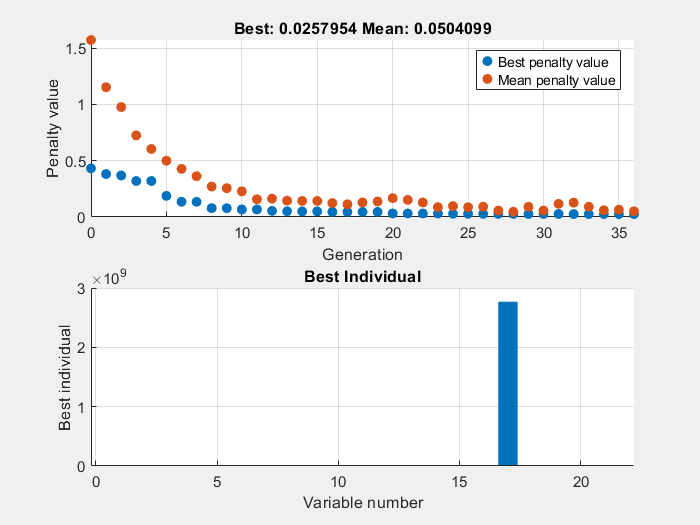

%%% Set GA parameters
lb = lb_total;
ub = ub_total;
intcon = [1,2,3,4,5,6,7,8,9,10,11,12,16]; 
nvars = 21;
nonlincon = @combinedNonlincon;
fun = @costObj;

%Vmax_placeholder = 10;
%numcars_placeholder = 16;

%setGlobalVars(Vmax_placeholder,numcars_placeholder)

%intcon for network and safety 
intcon_network = [1, 2, 3, 4,5, 6, 7,8,9,10,11,12,16];
intocon_train = [4];

%options copied from Quinn's code:
options = optimoptions('ga', ...
    'Display', 'iter', ...                          
    'PlotFcn', {@gaplotbestf, @gaplotbestindiv}, ... 
    'UseParallel', false, ...                        % switched to false
    'PopulationSize', 120, ...
    'EliteCount', ceil(0.15 * 120), ...             % 15% of population kept as elite
    'CrossoverFraction', 0.70, ...                   % 70% of population undergoes crossover
    'CrossoverFcn', @crossoverlaplace, ...          % good for real-valued obj funcs
    'MutationFcn', @mutationadaptfeasible, ...      % adaptive mutation but only in the feasible space
    'SelectionFcn', @selectiontournament, ...       % tournament selection
    'MaxGenerations', 120, ...
    'FunctionTolerance', 1e-3, ...                  % stop if improvement in func value is very small
    'ConstraintTolerance', 1e-3, ...                % tight, but not zero, tolerance on constraints
    'InitialPenalty', 5, ...
    'PenaltyFactor', 100, ...                       % quickly increase penalties for violating constraints
    'MaxStallGenerations', 20);                     % stop if no improvement (beyond tolerance) after 20 generations

%Run GA
[x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);

%calculate individual scores
convenience_score = networkScore(x_star(1:12))

convenience_score = single
-0.3695

train_veloc = TrainVelocity(predict(cd_mdl,x_star(13:16)))

train_veloc = 69.6610

number_of_accidents = accident_count_function(x_star(16:21))

number_of_accidents = 9.7811


fval_individual = [convenience_score, train_veloc, number_of_accidents];

%calculate individual costs
network_cost = networkCost(x_star(1:12))

network_cost = single
806290240

train_cost = TrainCost(x_star(16))

train_cost = 105000000

safety_cost = safety_system_cost_function(x_star(17:21))

safety_cost = 4.2893e+08

costs_individual = [network_cost, train_cost, safety_cost]

costs_individual = 1×3 single row vector
   806290240   105000000   428925376



Single objective optimization:
21 Variables
13 Integer variables
51 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible



                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.2539          0.9329        0
    2              360          0.2136          0.6177        0
    3              480          0.1773          0.4721        0
    4              600         0.03598          0.3372        0
    5              720         0.03598          0.2618        1
    6              840         0.03598           0.212        2
    7              960          0.0252          0.1899        0
    8             1080         0.01386          0.1133        0
    9             1200        0.004796         0.08046        0
   10             1320        0.004796         0.08243        1
   11             1440        0.002332          0.1091        0
   12             1560        0.002332         0.06418        1
   13             1680        0.002332         0.05817        2
   14             1800       0

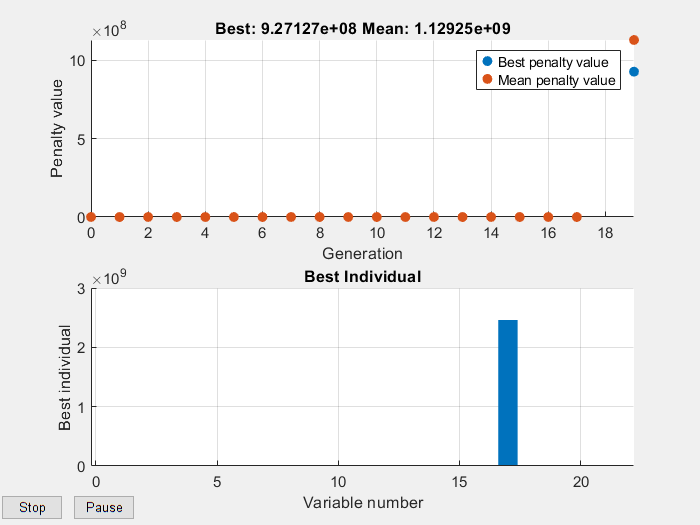

Error using networkCost (line 10)
Index in position 1 is invalid. Array indices must be positive integers or logical values.

Error in costObj (

% Sensitivity Analysis parameter sweep
% Sensitivity coefficients give the rate of change of the optimal values of
% the objective relative to small changes in the values of the constraints

% Constraints to sweep:
% Government Study comes out on train safety causing a mandate to regulate all train maximum speeds to ___.
% Government grant comes out for public transport, all costs to build stations are now halved.
% maxAccidentCount

%need to set these values as global variables
% [minCars, dist, maxAccidentCount]

%DistCon Parameter Sweep
% values tested: (20, 25, 30, 35, 40, 45, 50, 55, 60)
% GA run 10 times per value
%Set defaults:
minCars = 6;
dist = 35;
maxAccidentCount = 3;

setGlobalConstraintVars(minCars, dist, maxAccidentCount)

nonlincon = @combinedNonlinconSensitivityTesting;

%sweep dist hold other two parameters at defaults
x_star_sweep_dist = [x_initial]; %using x_initial just to set matrix size - probably a better way to do this
fval_sweep_dist = [];
sweep_vals_dist = [];

for k = 20:15:60 %temporarily changed 5 to 15; switch back after testing
    %set constraint values
    setGlobalConstraintVars(minCars, k, maxAccidentCount)

    %run GA 10 times per value
    %for j = 1:3 %changed 10 to 3; change back
        [x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);
        
        %save values
        x_star_sweep_dist(end+1,:) = x_star;
        fval_sweep_dist(end+1) = fval;
        sweep_vals_dist(end+1) = k;
    %end
end

%Accident Count Parameter Sweep
% values tested: (0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10)
% GA run 10 times per value


nonlincon = @combinedNonlinconSensitivityTesting;
% set defaults:
minCars = 6;
dist = 35;
maxAccidentCount = 3;

setGlobalConstraintVars(minCars, dist, maxAccidentCount)

%sweep maxAccidentCount hold other two parameters at defaults
x_star_sweep_accidents = [x_initial]; %using x_initial just to set matrix size - probably a better way to do this
fval_sweep_accidents = [];
sweep_vals_accidents = [];

for i = 0:10
    %set constraint values
    setGlobalConstraintVars(minCars, dist, i)

    %run GA 10 times per value
    for j = 1:2
        [x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);
        
        %save values
        x_star_sweep_accidents(end+1,:) = x_star;
        fval_sweep_accidents(end+1) = fval;
        sweep_vals_accidents(end+1) = i;
    end
end


Single objective optimization:
21 Variables
13 Integer variables
51 Nonlinear inequality constraints

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossoverlaplace
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible



                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.6136           1.164        0
    2              360          0.5613          0.9671        0
    3              480          0.3254          0.8117        0
    4              600          0.3254          0.6664        1
    5              720          0.3231          0.6108        0
    6              840           0.298          0.5268        0
    7              960          0.2971          0.4331        0
    8             1080           0.284           0.398        0
    9             1200          0.2484          0.3682        0
   10             1320          0.2484          0.3839        1
   11             1440          0.2337          0.3374        0
   12             1560          0.2154          0.3062        0
   13             1680          0.2154          0.2845        1
   14             1800        


                                  Best          Mean         Stall
Generation      Func-count     Penalty         Penalty    Generations
    1              240          0.4976           1.085        0
    2              360          0.4439          0.8027        0
    3              480          0.4014           0.652        0
    4              600          0.3643          0.5854        0
    5              720           0.285          0.5202        0
    6              840           0.285          0.4606        1
    7              960           0.285          0.4411        2
    8             1080          0.2374          0.4503        0
    9             1200          0.2374          0.3547        1
   10             1320          0.2374           0.409        2
   11             1440          0.2109          0.3755        0
   12             1560          0.2109          0.3911        1
   13             1680          0.2037          0.3268        0
   14             1800        

%minCars Parameter Sweep
% values tested: (0, 1, 2, 3, 4, 5, 6, 7, 8, 9, 10)
% GA run 10 times per value
% set defaults:
minCars = 6;
dist = 35;
maxAccidentCount = 3;

setGlobalConstraintVars(minCars, dist, maxAccidentCount)

%sweep minCars hold other two parameters at defaults
x_star_sweep_minCars = [x_initial]; %using x_initial just to set matrix size - probably a better way to do this
fval_sweep_minCars = [];
sweep_vals_minCars = [];

for i = 0:10
    %set constraint values
    setGlobalConstraintVars(minCars, dist, i)

    %run GA 10 times per value
    for j = 1:10
        [x_star,fval,exitflag,output,population,scores] = ga(fun,nvars,[],[],[],[],lb,ub,nonlincon,intcon,options);
        
        %save values
        x_star_sweep_minCars(end+1,:) = x_star;
        fval_sweep_minCars(end+1) = fval;
        sweep_vals_minCars(end+1) = i;
    end
end

%plot values
figure()
plot(sweep_vals_dist,fval_sweep_dist)
xlabel("Minimum Distance Between Stations (km)")
ylabel("totalCost")

% %shared variables are: 
% %Output from safety optimization: Vmax (x(21)) --> input to train optimizer
% %Output from train optimization: number of cars (gives mass) (x(16)) ---> parameter in safety optimization 
% 
% %network: (x(1:12))
% %train: (x(13:16))
% %safety: (x(17:21))
% 
% %FPI/MDF:
% %First iteration:
% %set initial placeholders for shared variables
% Vmax_placeholder = 10;
% numcars_placeholder = 16;
% 
% setGlobalVars(Vmax_placeholder,numcars_placeholder)
% %r = getGlobalVars; %for testing 
% 
% % add to beginnning of functions as necessary:
% % [r1, r2] = getGlobalVars;
% % numberofcars = r2;
% % Vmaximum = r1;
% 
% %set epselom (to tune)
% epselom = 0.0001;
% 
% %run GA on network
% [x_network,fval_network,exitflag_network,output_network,population_network,scores_network] = ga(@networkCost,12,[],[],[],[],lb_network,ub_network,nonlincon_network,intcon_network,options);
% 
% %run GA on train
% [x_train,fval_train,exitflag_train,output_train,population_train,scores_train] = ga(@TrainCost,4,[],[],[],[],lb_train,ub_train,nonlincon_train,intcon_train,options);
% 
% %run GA on safety (should be no intcon for this subsystem)
% [x_safety,fval_safety,exitflag_safety,output_safety,population_safety,scores_safety] = ga(@safety_system_cost_function,5,[],[],[],[],lb_safety,ub_safety, nonlincon_safety,intcon,options);
% 
% %enter while loop, compare placeholder to calculated values
% %If not same, iterate until they converge
% while (((Vmax_placeholder - Vmax) > epselom) && ((numcars_placeholder - numcars) > epselom));
%     %reset placeholer values to last calculated value
%     Vmax_placeholder = x_safety(5);
%     numcars_placeholder = x_train(4);
%     setGlobalVars(Vmax_placeholder,numcars_placeholder);
% 
%     %run GA on network
%     [x_network,fval_network,exitflag_network,output_network,population_network,scores_network] = ga(@networkCost,12,[],[],[],[],lb_network,ub_network,nonlincon_network,intcon_network,options);
%     
%     %run GA on train
%     [x_train,fval_train,exitflag_train,output_train,population_train,scores_train] = ga(@TrainCost,4,[],[],[],[],lb_train,ub_train,nonlincon_train,intcon_train,options);
% 
%     %run GA on safety (should be no intcon for this subsystem)
%     [x_safety,fval_safety,exitflag_safety,output_safety,population_safety,scores_safety] = ga(@safety_system_cost_function,5,[],[],[],[],lb_safety,ub_safety, nonlincon_safety,intcon,options);
% end
% 
% %combine for overall x_star and calculate total cost
% x_star = [x_network, x_train, x_safety]
% total_cost = costObj(x_star)



